# Position control

We should now have the most basic controllers already in place: we have a vertical stabilization system, a PFC current controller, and a plasma current controller. We shall now address the problem of **plasma position control**.

## Preliminaries

As for the other exercises, here we will use our CREATE-NL plasma equilibrium and CREATE-L linearized model to design our controllers. However, remember that these models are obtained through a custom FEM code and a carefully designed linearization procedure. Having such a tool is very useful, but it was not at all common in the early days of plasma control, and in this way we are somehow cheating, hiding the dust of complexity under the rug. For this reason, it is instructive to take a step back and turn our attention to a simpler model: the so-called **RZIp model.**

RZIp simply stands for R(radial) + Z(vertical) + Ip(plasma current), and it is a "simple" model used to describe the plasma (rigid) vertical and radial motion plus the variations in the plasma current. Different variations on such a model exist, we'll take a look at one possible formulation. Along the way, we will examine the basic aspects of ***toroidal force balance*** in tokamaks and provide an expression for the $B_V$ field seen in the VS exercise (we'll mostly stick to a **qualitative picture **and provide an overview of some classic results).

### Radial force balance

We have already seen that:

- elongated plasma configurations are vertically unstable, calling for an active stabilization system

- plasma current need to be regulated, in order to counteract resistive drop and noninductive current sources

These issues arise even in the most crude plasma models, e.g. if we consider the plasma as a rigid filament carrying a current. However, tokamaks are much more complex than this. The basic recipe for a tokamak is based on the so-called *screw pinch, *i.e. a plasma cylinder with an helical current/field pattern; the parents of the screw-pinch are the *Z-pinch *(roughly: good confinement properties) and the $\theta$*-pinch *(roughly: good stability properties), two early cylindrical plasma confinement configurations. The main drawback of cylindrical devices is that they loose plasma at the ends: so, the scientists of the early days of fusion research had the idea to bend them into *doughnut-shaped* machines: most modern toroidal fusion devices (tokamaks, RFPs, stellarators) are, at least to some extent, consequences of this first idea.

However, when we bend the plasma column into a torus, suddenly we are faced with a deformable ring of ionized gas at 100 million degrees. In particular, with respect to a current-carrying wire, plasma can *change shape,* and the first consequence is that it is **subject to *****radial forces***, as well as to vertical ones.

In particular, the three main radial forces that appear are:

- the **tire-tube** force

- the **hoop** force

- the **1/R** force

#### Tire-tube force

The LCFS can be seen as an isobaric line. Bending the plasma makes the external surface larger, and since force is pressure times surface, as a result we have a **net outward force**.

Note that this effect arises in both toroidal Z-pinches and $\theta$-pinches, as it depends on pressure.

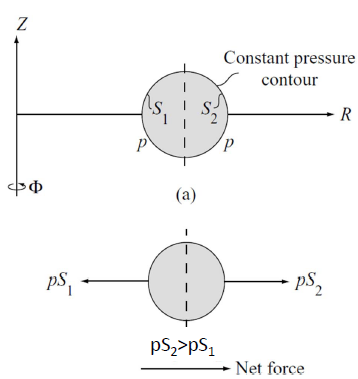

#### Hoop force

We all know that a closed loop carrying a current suffers some **E+M stresses** which tend to tear it apart. Usually, a wire is made of some solid conducting material (aka metal), so that's not a big deal. However, things are different with plasma.

At a closer inspection, it turns out that the field is *stronger* in the inside of the doughnut (it's not a case that it is called the "**high field side**" of the tokamak...). B lines are packed more closely on the inside than on the outside, and the result is -again- a **net outward force**. 

Another way to look at this is that the so-called **magnetic pressure** scales as $B^2$, and the quadratic scaling of the field dominates over the S scaling.

Note that here we are looking at the poloidal field only. This effect arises when we bend Z-pinches: the toroidal current is responsible of this effect.

 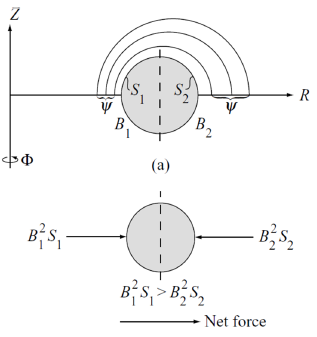

#### 1/R force

Finally, bending the plasma into a torus results in the fact that the toroidal field has an inverse dependence on the radius (as in the well-known formula for the field inside a toroidal solenoid). Remember that the current flows helically on the flux surfaces, so current also has a poloidal component, whose interaction with the field results -*again!*- in a **net outward force**.

This effect arises in $\theta$-pinches: this time, it is the poloidal current which is to blame (just to get the idea, imagine an approximately constant surface current density which interacts with a toroidal field that varies in space).

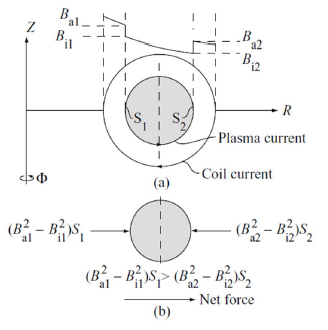

#### Restoring force

We have two ways of counteracting these effects

- surrounding the plasma with a (perfectly) **conducting wall**

- adding a **vertical magnetic field**

In the first case, the wall "traps" the field lines, which get compressed as the plasma moves outward. The increased value of the magnetic field results in a **restoring magnetic pressure. **Notice that this can only be done when a poloidal field is present, i.e. for Z-pinches. That is one reason why adding a pinch of Z-pinch to our tokamak recipe is a good idea: we can easily provide stabilizing radial and vertical forces.

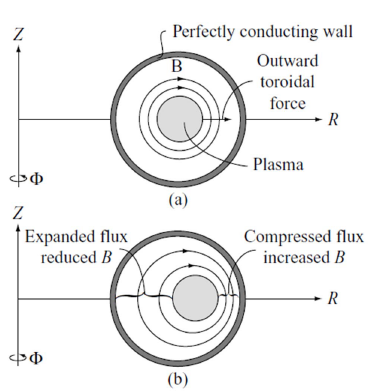

However, as we have already seen** perfect walls do not exist! **The walls are always **resistive**, and eventually the flux diffuses across the wall. While this approach works on short time scales, unfortunately we cannot trap a plasma indefinitely in this way (without taking into account the fact that a perfectly conducting wall would be a pain in the neck during breakdown - see what happened at WEST a few years ago...)

In the second case, we can carefully choose the magnitude of the **applied field** in order to balance the net outward force

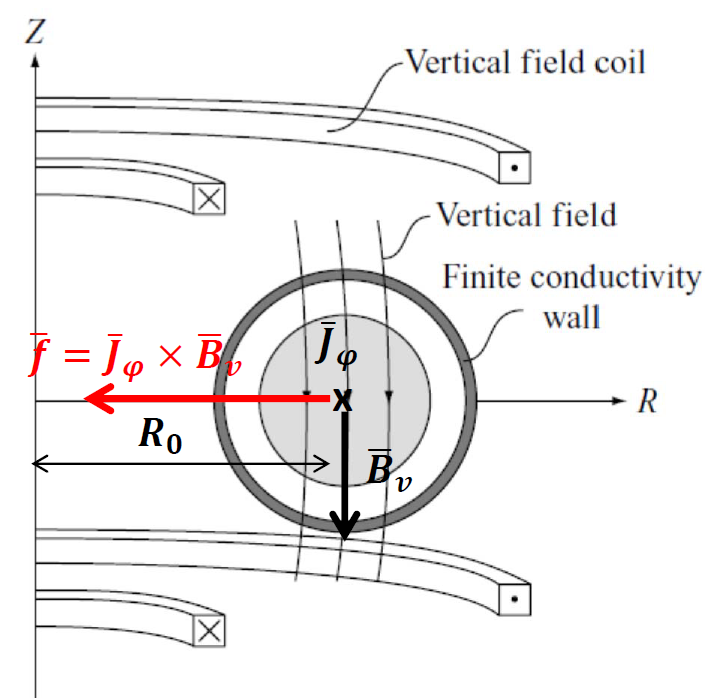

This field is the $B_V$ that we saw when talking about the VS system!

Without digging into messy calculations, we just mention that, at least **for a circular, high aspect ratio plasma**, the resulting forces can be calculated analytically as

- **Tire-tube**: $F_1 = \frac{\mu_0 I_p^2}{4} \beta_p$                            notice how this force depends on *pressure* through $\beta_p := \frac{<p>_{V_p}}{\frac{B^2_p(a)}{2\mu_0}} = \frac{4 \int_{V_p} p dV}{\mu_0 R_0 I_p^2}$;

- **Hoop**:      $F_2 = \frac{1}{2}\mu_0 I_p^2 \left[\ln \frac{8 R_0}{a} -1 + \frac{l_i}{2}\right]$     notice how this force depends on the (*toroidal)* *current distribution* through $l_i := \frac{<B_p^2>_{V_p}}{B_p^2(a)} = \frac{4 \int_{V_p} \frac{B^2}{2\mu_0} dV}{\mu_0 R_0 I_p^2}$;

- **1/R**:          $F_3 = 2 \pi^2 a^2 \left[ \frac{B^2_\phi (a)}{2\mu_0} - \frac{<B_\phi^2>}{2\mu_0}  \right]$  notice how this force depends on the *toroidal field* $B_\phi$. 

It can be shown that the 1/R force can also be rewritten as


$$F_3 = \frac{\mu_0}{4}I_p^2 (\beta_p - 1)$$
 

and hence the net resulting force is 


$$F_R = F_1 + F_2 + F_3 = \frac{\mu_0}{2} I_p^2 \left[ \ln \frac{8 R_0}{a} + \beta_p + \frac{l_i}{2} -\frac{3}{2}  \right]$$


The term in square brackets is often referred to as $\Gamma$ and is a function of the minor radius $a$, of the major radius $R_0$, of the poloidal beta $\beta_p$ and of the internal inductance $l_i$.

We need to apply a force (along the negative radial direction) equal and opposite to $F_R$ through an appropriate choice of the vertical field:


$$F_V = -I_p B_V 2 \pi R_0 \hat{r}$$
 

Hence


$$B_V = \frac{\mu_0 I_p}{4 \pi R_0} \left[  \ln \frac{8 R_0}{a} + \beta_p + \frac{l_i}{2}  -\frac{3}{2}   \right]$$


## The RZIp model

We are now ready to present the equations forming the RZIp model. RZIp is a LTI model used to describe plasma-vessel coupled dynamics. The main assumption is that **the plasma current distribution remains constant **during any control action, while **the centroid can move** both vertically and radially and **the plasma current** (i.e. the integral of the current density) **can change** over time.

The model takes into account the currents in the active circuits, the passive structures (usually through a filamentary model) and the total plasma current. Often, **the plasma is represented by a set of filamentary currents **(but simpler versions of this model may use a single filament of variable radius). The RZIp equations are:


$$L_a \dot{I}_a + R_a I_a + M_{ae} \dot{I}_e + \dot{\psi}_{ap} = V_a \\
L_e \dot{I}_e + R_e I_e + M_{ea} \dot{I}_a + \dot{\psi}_{ep} = 0 \\
m_p \ddot{z}_p = - 2 \pi r_p I_P \bar{B}_r(r_p,z_p,I_a,I_e,I_p) \\
m_p \ddot{r}_p = + 2 \pi r_p I_P \bar{B}_z(r_p,z_p,I_a,I_e,I_p) + F_r(r_p,I_p,\beta_p,l_i) \\
\frac{d}{dt} \left[  L_p I_p \right] + R_p I_p + \dot{\psi}_{pa} + \dot{\psi}_{pe} = 0$$


where

- $M_{ae}, M_{ea}$ and $R_{a,e}$ are the matrices containing **self and mutual inductances** of the conducting elements (coil and passive structures) and their **resistances**

- $\psi_{ap}, \psi_{ep}$ represent the **flux due to the plasma current distribution** enclosed by the active and passive circuits respectively. A generic element of these vectors can be written as $\psi_{(ae)p,k} = M_{(ae)kp} I_p = \int_{plasma} \tilde{M}_{(ae)kJ}(r,z)J(r,z) dr dz$, $k$ is the index of the considered circuit, $J$ is the current density distribution obtained from a reference equilibrium and $\tilde{M}_{(ae)kJ}$ is the mutual inductance between the $k$-th active/passive circuit and the points on the poloidal plane where the current density is evaluated.

- $\psi_{p(ae)}$ contain the **flux due to the surrounding circuits** enclosed by the plasma, which can be written as $\psi_{p(ae)}=\sum_k M_{p(ae)k} I_{(ae)k}$, again with $k$ index of the considered active/passive circuit. Notice that these terms depend both on the active/passive currents and the plasma filaments position!

- $(\bar{B}_r,\bar{B}_z)$ are the **components of the magnetic field generated by the external conductors** and acting on the plasma, computed as a weighted average of the Lorentz force due to the poloidal magnetic field $(B_r, B_z)$ generated by the external conductors and acting on the toroidal plasma current distribution

- $F_r$ is the **net radial outward force** deriving from plasma pressure and tokamak toroidal geometry, which (as we have seen) is a function of $\beta_p$ and $l_i$, of the total plasma current $I_p$ and of the plasma radial position $r_p$.

As you can see, with respect to the filamentary model seen in the VS exercise, here we kept the equations describing the dynamics of the active and passive currents, but **we allowed the plasma current to change** and we added the **radial force balance equation**. Moreover, often in RZIp models, **more than a single plasma filament is used**, each filament carrying a current that is related to the internal plasma current profile (and the fields/forces are averaged over the plasma current distribution).

Again, in most cases the plasma is assumed to be *massless*, i.e. $m_p \rightarrow 0$. This can be formally seen as a the application of the *singular perturbation *method: we substitute equations (2) and (3) in the model above with static relations that need to be satisfied.

After this short overview, we are ready to design our controller.

## RZIp control using a CREATE-L model

Let's see how we can design a RZIp controller with our CREATE-L/NL model. RZIp controllers are often used in the **early phases** of a discharge, when the plasma is still **limiter** and shape control is not active yet. We have already designed an $I_p$ controller, and we know that (if we have done everything the right way) it should be decoupled from the plasma position/shape dynamics. So, what we actually need to do is to design the controllers for $r_p$ and $z_p$.

Also notice that, usually, vertical stabilization is in charge of *stopping* the vertical motion of the plasma, i.e. bringing the vertical velocity to zero. On the other hand, **RZIp controls the *****position***** of the plasma**, regulating it to a desided value (usually on slower time scales). This choice is made so that the two controllers do not interact (in a bad sense).

For simplicity, we'll keep working with our SOF model of JT-60SA. We start by loading our model and extracting the quantities of interest

addpath ./functions
addpath ./models
addpath ./data 

modelName = fullfile(pwd,'models','SOF@18d66s_FG.mat');
model = load(modelName);

lm.A = -model.L\model.R;
lm.B =  model.L\eye(size(model.L));
lm.C =  model.C;
lm.D =  zeros(size(lm.C,1), size(lm.B,2));
lm.E = -model.L\model.LE;
lm.F =  model.F;

% Get C-matrix for rp and zp
i_rp = get_y_idx(model.y_type,'Rpl',1);
C_rp = lm.C(i_rp,:);

i_zp = get_y_idx(model.y_type,'Zpl',1);
C_zp = lm.C(i_zp,:);

To simplify our problem, we can try to decouple the two controllers by separating the plant into two SISO systems. To do so, we may choose current combinations which provide an approximately vertical/radial field, and use them as actuators. Let's look again at the geometry of JT-60SA (this time adding the names of the coils to the plot)

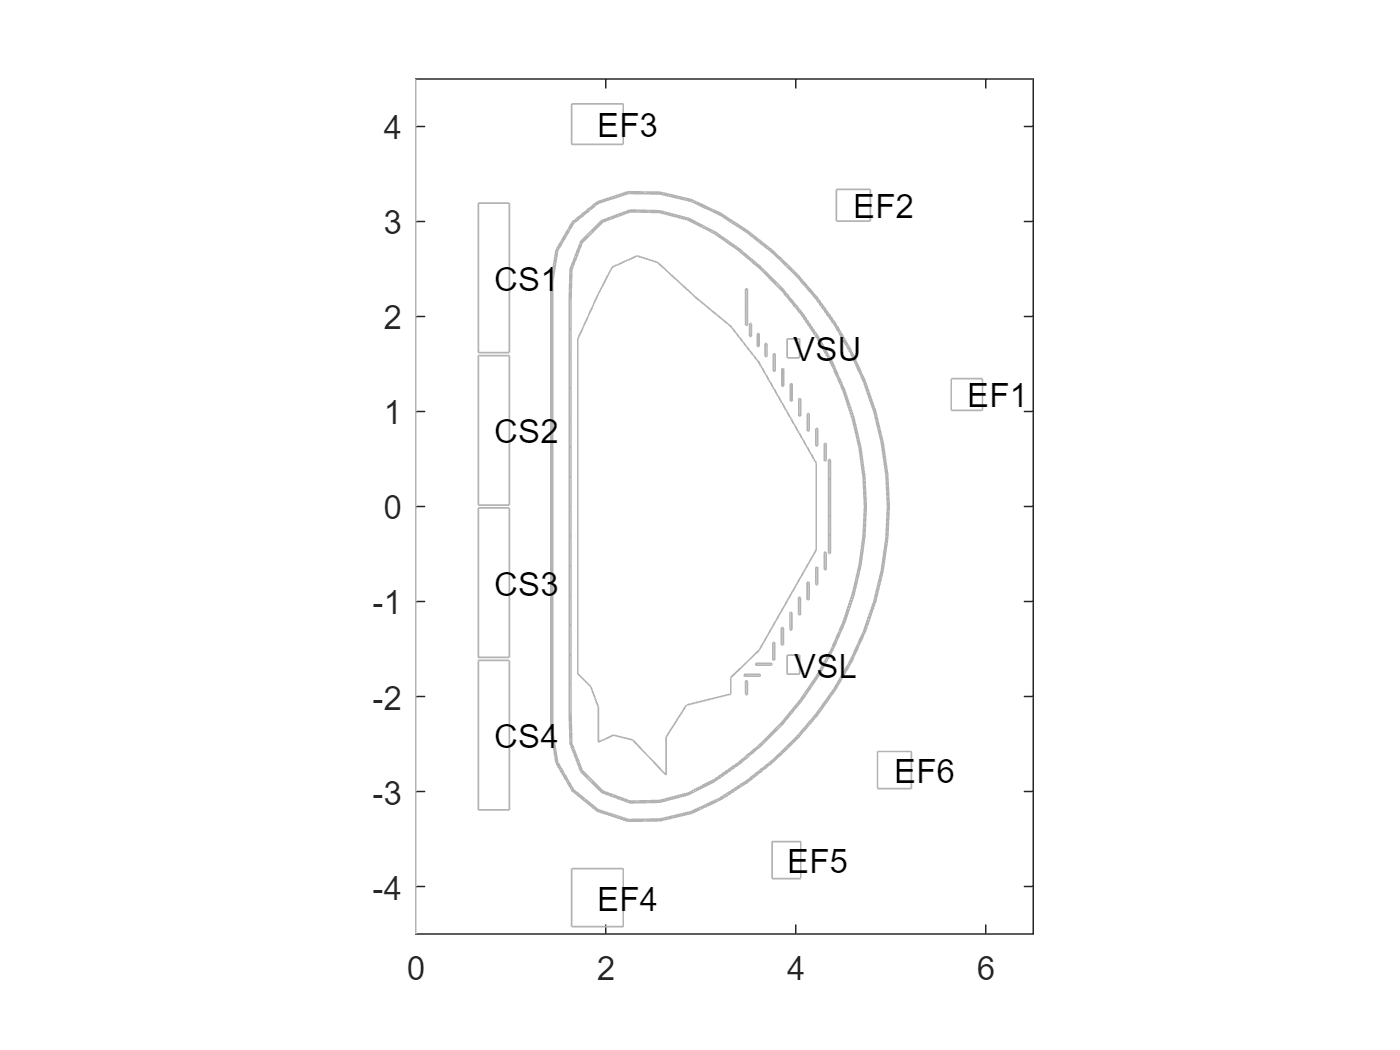

plot_mesh(model.Input_struct);
hold on

circuitNames = model.y_type(1:12,1);
for i = 1 : 12
  text(model.preproc_struct.Rcond(i),model.preproc_struct.Zcond(i),circuitNames{i});
end
xlim([ 0.0 6.5])
ylim([-4.5 4.5])

The coils are not exactly symmetric, but we observe that the coils CS1-CS2-EF1-EF2-EF3-VSU are (approximately) a mirror image of CS3-CS4-EF6-EF5-EF4-VSL.

We have seen that the CS coils are heavily used by the plasma current controller and the VS are reserved to the vertical stabilization, so let's use the **EF** coils for RZ control.

To inspect the field patterns generated by these coils, we use again our plasmaless model (this is the same code used for the VS system, so I'll add no comments here):

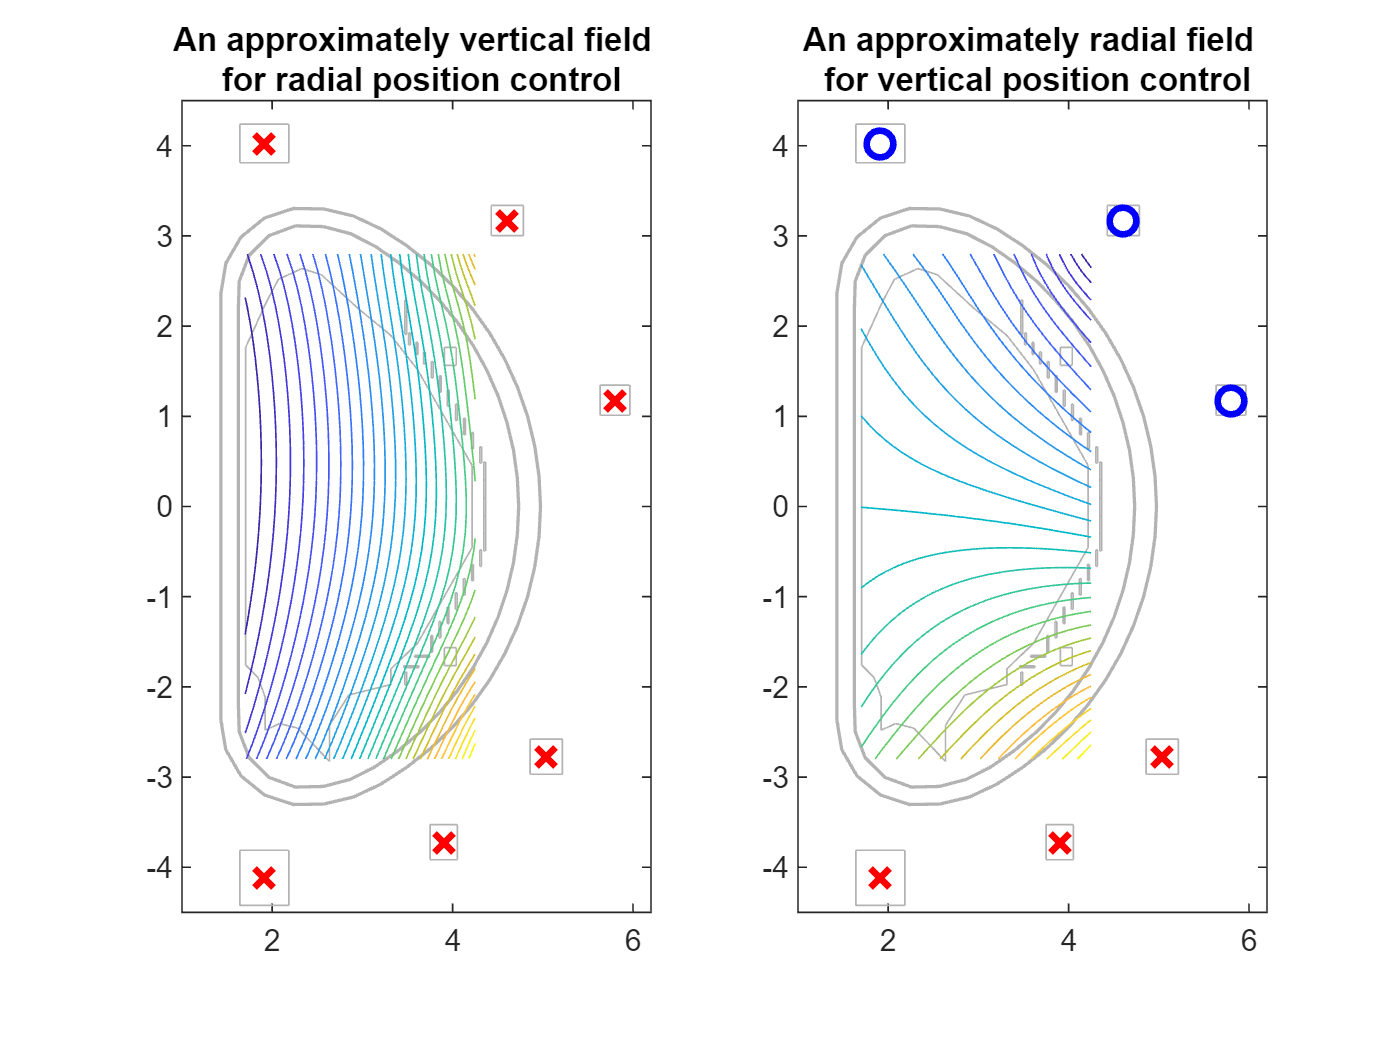

plasmalessName = fullfile(pwd,'models','plasmaless_FG.mat');
plasmaless = load(plasmalessName);
pm.A = -plasmaless.L\plasmaless.R;
pm.B = plasmaless.L\eye(size(plasmaless.L));
pm.C = plasmaless.C;
pm.D = zeros(size(pm.C,1), size(pm.B,2)); % just a bunch of zeros

i_fg = get_y_idx(plasmaless.y_type,'Flux_grid');
n_fg = plasmaless.y_type(i_fg,1);
r_fg = plasmaless.Input_struct.r_sens(contains(plasmaless.Input_struct.names_sensors,n_fg));
z_fg = plasmaless.Input_struct.z_sens(contains(plasmaless.Input_struct.names_sensors,n_fg));


% Current patterns (we use the EF coils only)
ncoils = 10; % only PF-coils
dI_r = [0, 0, 0, 0, +1, +1, +1, +1, +1, +1]'; % pattern for radial control
dI_z = [0, 0, 0, 0, -1, -1, -1, +1, +1, +1]'; % pattern for vertical control

C_fg = pm.C(i_fg,1:ncoils);
dy_r   = C_fg*dI_r;
dy_z   = C_fg*dI_z;

R_fg = reshape(r_fg,30,30);
Z_fg = reshape(z_fg,30,30);
dY_r = reshape(dy_r,30,30);
dY_z = reshape(dy_z,30,30);

% plots
figure
subplot(121)
plot_mesh(plasmaless.Input_struct);
hold on
contour(R_fg,Z_fg,dY_r,31)
xlim([ 1.0 6.2])
ylim([-4.5 4.5])
for i = 1 : ncoils
  if dI_r(i) ~= 0
    if dI_r(i)>0, color = 'xr'; else, color = 'ob'; end
    plot(model.preproc_struct.Rcond(i),model.preproc_struct.Zcond(i),color,'linewidth',2,'Markersize',8)
  end
end
title(sprintf('An approximately vertical field \n for radial position control'))

subplot(122)
plot_mesh(plasmaless.Input_struct);
hold on
contour(R_fg,Z_fg,dY_z,31)
xlim([ 1.0 6.2])
ylim([-4.5 4.5])
for i = 1 : ncoils
  if dI_z(i) ~= 0
    if dI_z(i)>0, color = 'xr'; else, color = 'ob'; end
    plot(model.preproc_struct.Rcond(i),model.preproc_struct.Zcond(i),color,'linewidth',2,'Markersize',8)
  end
end
title(sprintf('An approximately radial field \n for vertical position control'))

Not perfect, but it should work (in up-down symmetric machines this is straightforward; probably we could do better by carefully tuning the weights of the coils, but this should be enough for now).

Let's use these combinations to obtain a 2 inputs - 2 outputs plant. If we are lucky, the vertical and radial dynamics should be almost decoupled.

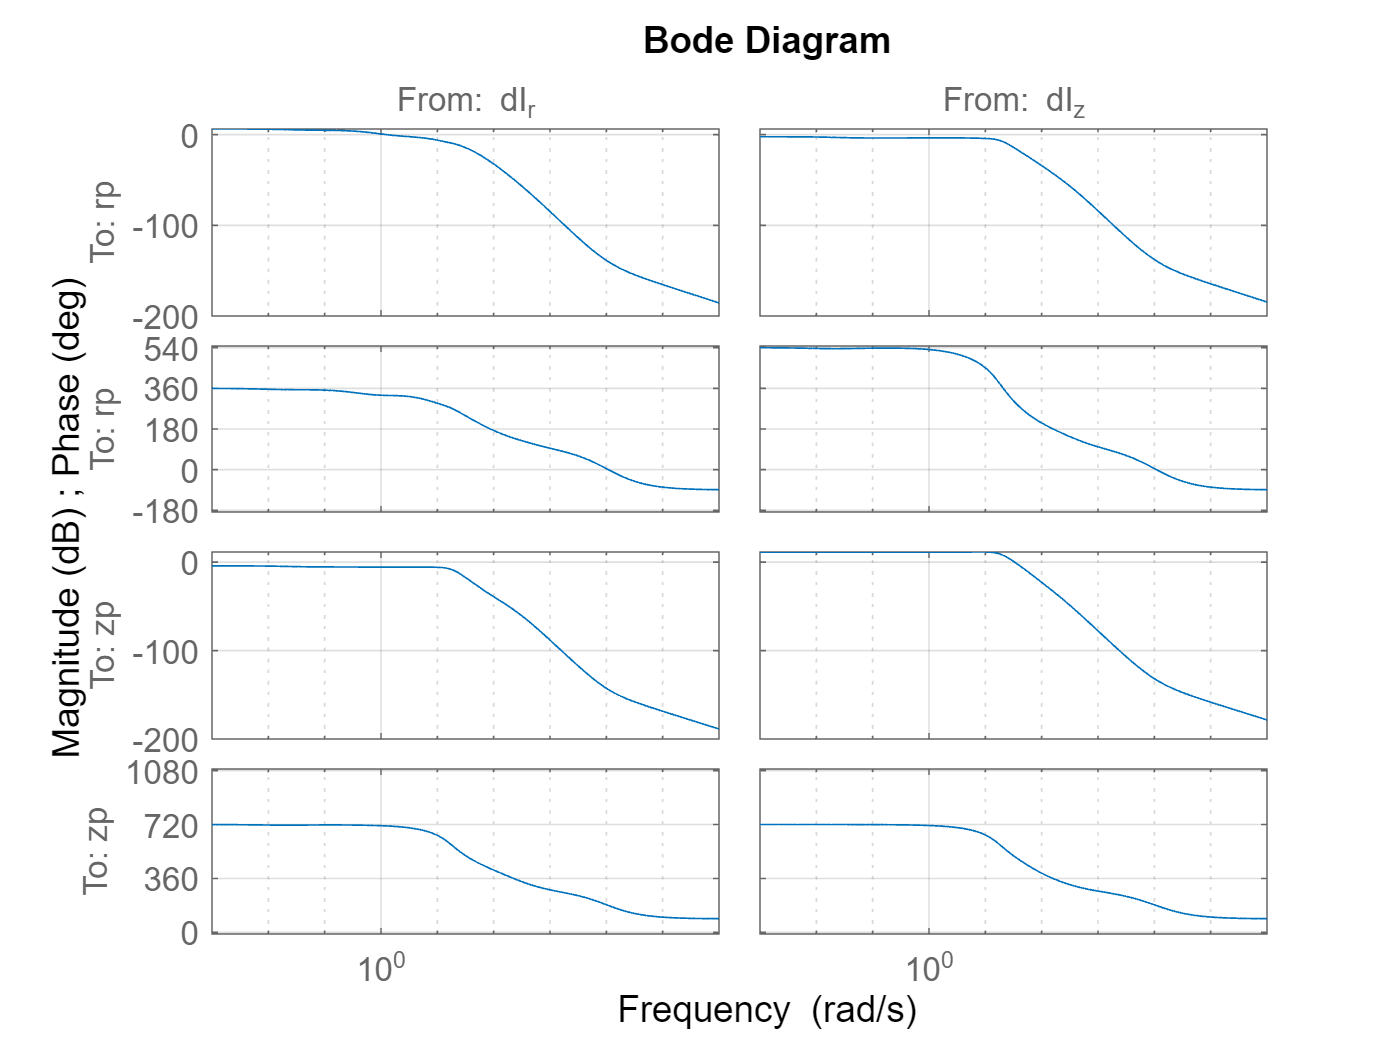

% Load ss model
load PF_contr.mat PF_clsys

% Change the output equation of the PFC closed-loop system
RZ_olsys = ss(PF_clsys.a,PF_clsys.b,lm.C([i_rp i_zp],:),lm.D([i_rp i_zp],1:10));

% Assign I/Os
Inames = model.y_type(1:10,1);
RZ_olsys.inputname  = Inames;
RZ_olsys.outputname = {'rp','zp'};

% Use current combinations 
figure
RZ_decoupled_sys = RZ_olsys*[dI_r,dI_z]*1e4; % add a x1e4 factor to get a reasonable dc gain
RZ_decoupled_sys.inputname = {'dI_r','dI_z'};
bode(RZ_decoupled_sys); 
grid on

We can take a look at the dc-gains of our open loop transfer functions

dcgain(RZ_decoupled_sys)

ans =     2.0518   -0.7651
    0.6177    3.6685


As you can see, the gains on the diagonal are about one order of magnitude larger than the ones off-diagonal. The decoupling is not perfect (the off-diagonal gains are still large) but should be sufficient for our purpose.

For the sake of completeness, let's put all the bode plots on the same graph

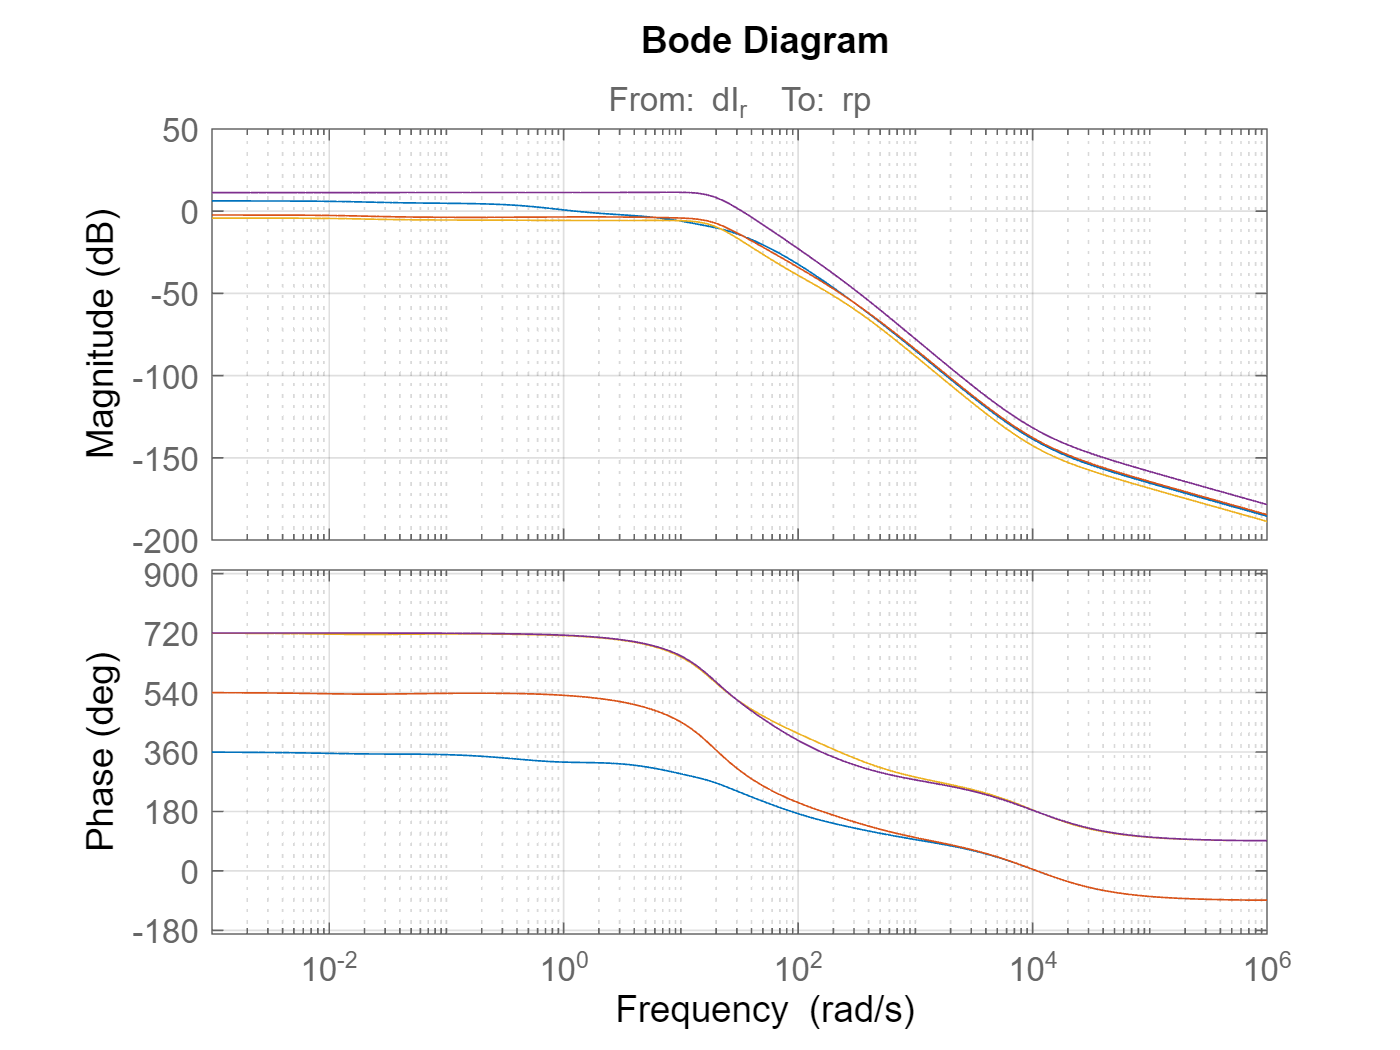

figure
hold on
for i = 1:2
  for j = 1:2
    h = bodeplot(RZ_decoupled_sys(i,j));
  end
end
grid on

We can also see what happens if we apply these current patterns to our equilibrium.

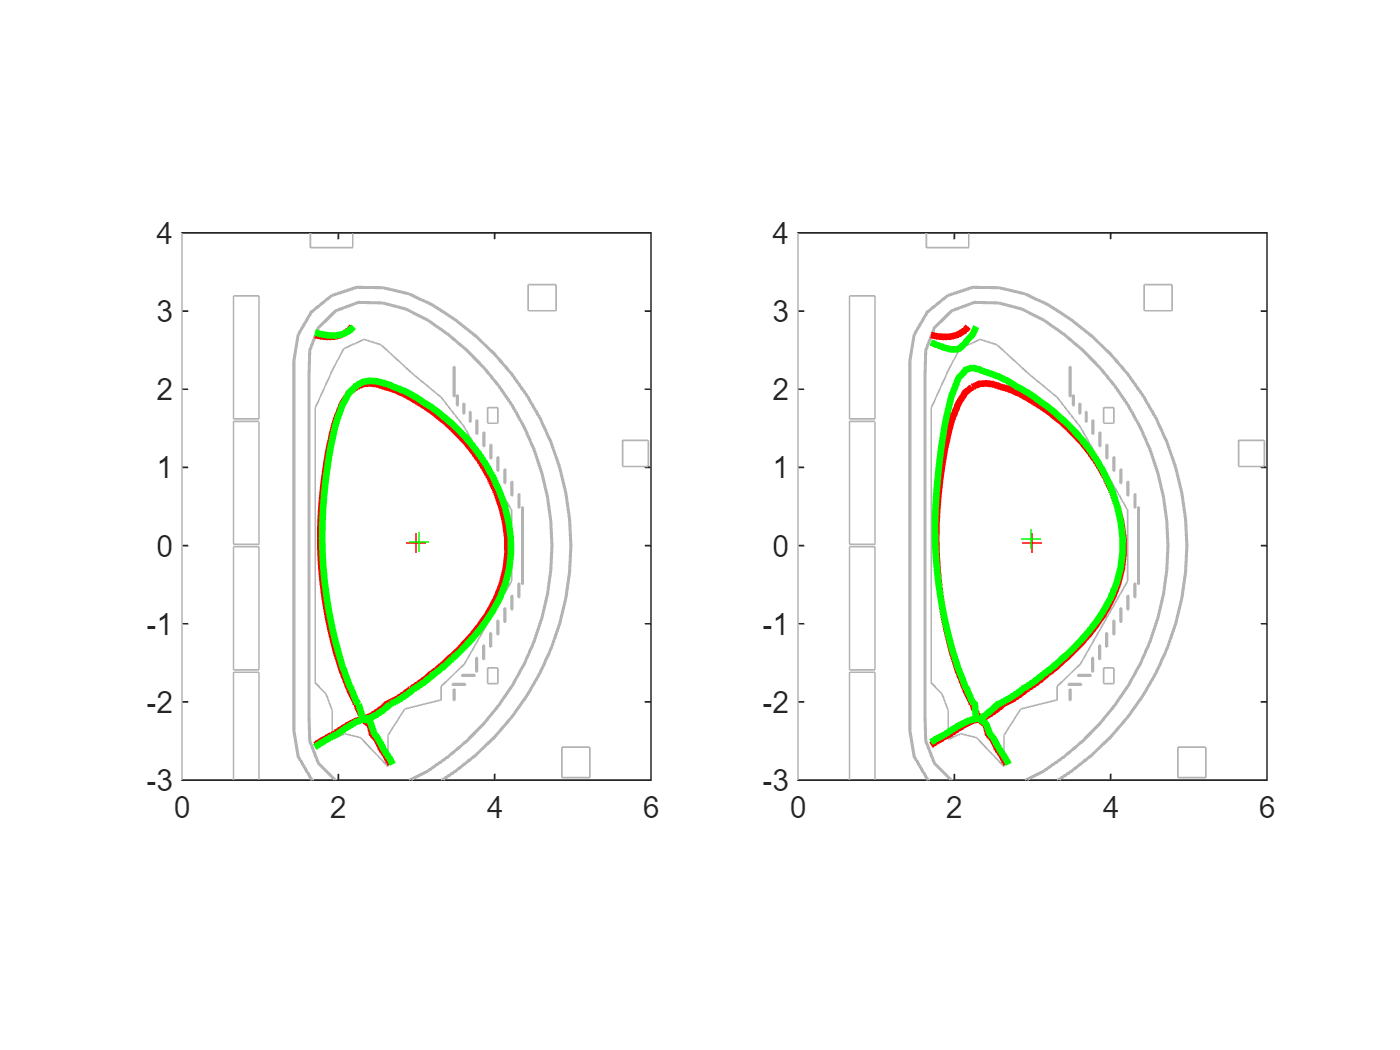

i_psb = get_y_idx(model.y_type,'psb_c');
i_fg = get_y_idx(model.y_type,'Flux_grid');
n_fg = model.y_type(i_fg,1);
r_fg = model.Input_struct.r_sens(contains(model.Input_struct.names_sensors,n_fg));
z_fg = model.Input_struct.z_sens(contains(model.Input_struct.names_sensors,n_fg));

C_fg  = model.C(i_fg,1:10);
C_psb = model.C(i_psb,1:10);

C_rp2 = C_rp(:,1:10);
C_zp2 = C_zp(:,1:10);

eq_fg   = model.y_np(i_fg);  % equilibrium values of the virtual sensors (notice that there is a factor 2pi between the sensors and the GS solution)
eq_psib = model.y_np(i_psb);
eq_rp   = model.y_np(i_rp);
eq_zp   = model.y_np(i_zp);

R_fg = reshape(r_fg,30,30); % reshape into a matrix
Z_fg = reshape(z_fg,30,30);
E_fg = reshape(eq_fg,30,30);

% Flux modifications with considered current patterns x i0
i0 = 150;
dy_r    = C_fg*dI_r*i0;
dy_z    = C_fg*dI_z*i0;
dpsib_r = C_psb*dI_r*i0;
dpsib_z = C_psb*dI_z*i0;
drp_r   = C_rp2*dI_r*i0;
dzp_r   = C_zp2*dI_r*i0;
drp_z   = C_rp2*dI_z*i0;
dzp_z   = C_zp2*dI_z*i0;

% Convert into grid format
dY_r = reshape(dy_r,30,30);
dY_z = reshape(dy_z,30,30);

% Plot
figure;
subplot(121)
plot_mesh(model.Input_struct);
hold on
contour(R_fg,Z_fg,E_fg,eq_psib*2*pi*[1 1],'r','linewidth',2)
plot(eq_rp,eq_zp,'+r');
hold on
contour(R_fg,Z_fg,E_fg+dY_r,(eq_psib+dpsib_r)*2*pi*[1 1],'g','linewidth',2)
plot(eq_rp+drp_r,eq_zp+dzp_r,'+g');
xlim([0 6])
ylim([-3 4])

subplot(122)
plot_mesh(model.Input_struct);
hold on
contour(R_fg,Z_fg,E_fg,eq_psib*2*pi*[1 1],'r','linewidth',2)
plot(eq_rp,eq_zp,'+r');
hold on
contour(R_fg,Z_fg,E_fg+dY_z,(eq_psib+dpsib_z)*2*pi*[1 1],'g','linewidth',2)
plot(eq_rp+drp_z,eq_zp+dzp_z,'+g');
xlim([0 6])
ylim([-3 4])

As you can see, by applying our current patterns we get a mostly radial displacement in the first case, and a mostly vertical one in the second case. All good.

## RZ controller design

We can now move on to design our controllers. We will use again PI controllers.

Again, note that this is not the optimal way of proceeding, and we could probably do much better by using more sophisticated approaches to decouple our MIMO system. However, this simple example has the advantage of showing how we can combine physical domain expertise and control design techniques in a simple but effective way.

We need to design two SISO control loops; we'll make them robust, and hope that the controllers are able of fully decoupling the dynamics. We'll design our controller in the frequency domain.

Let's start with $rp$

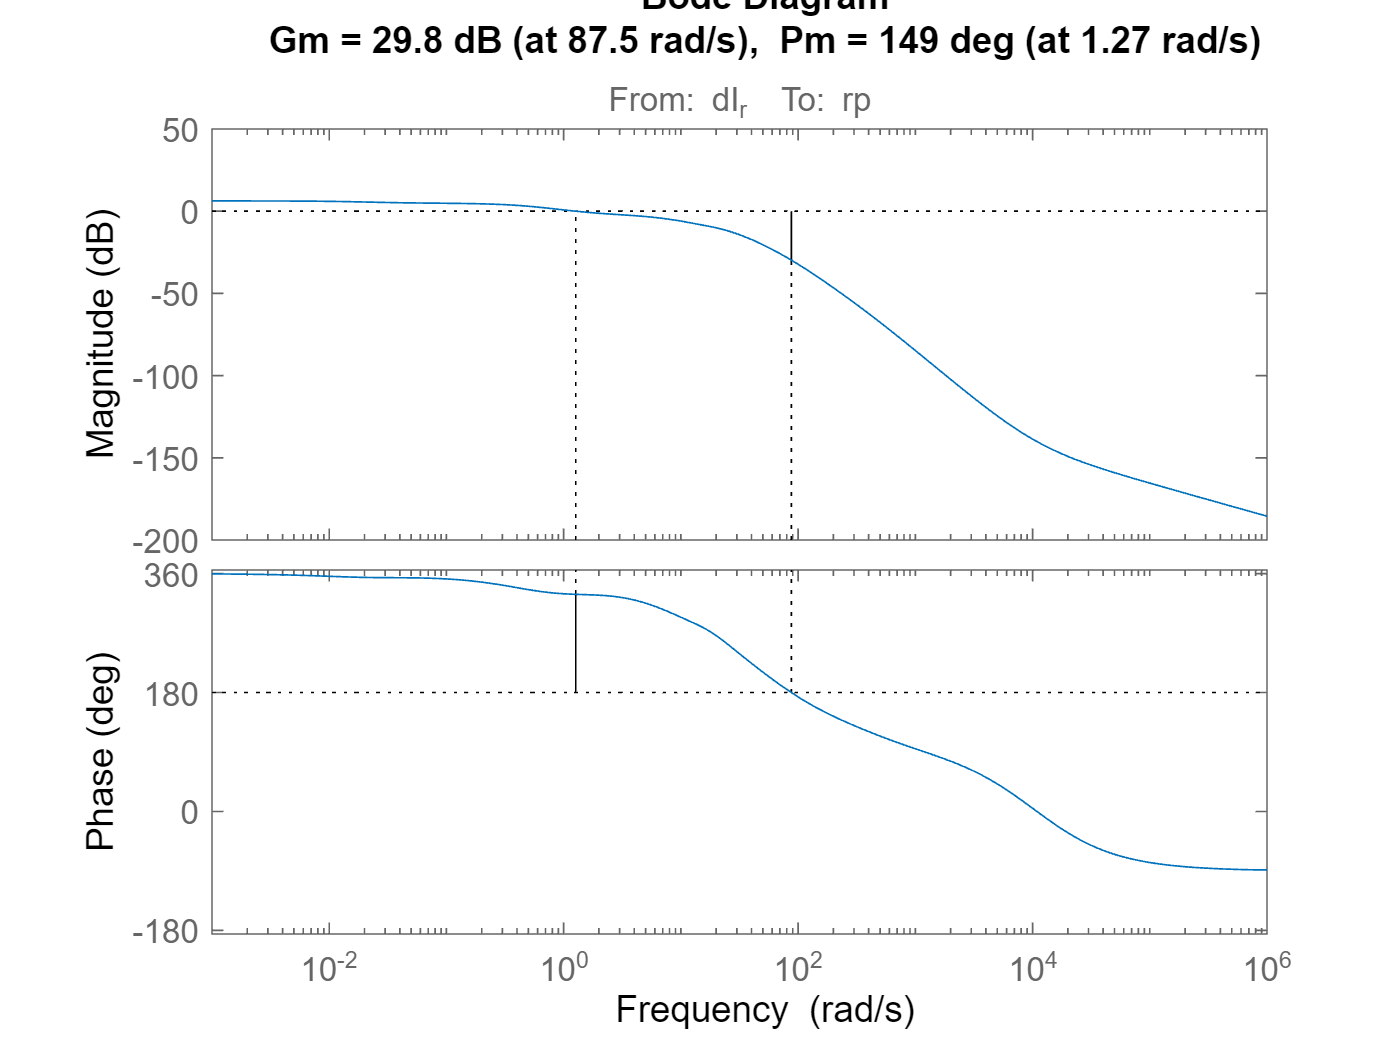

R_olsys = RZ_decoupled_sys(1,1);
figure
margin(R_olsys)

This is actually already pretty good, we have a decent bandwidth and a very high phase margin. 

We may want to add a bit of integral action to get zero error at regime and increase the bandwidth a little:

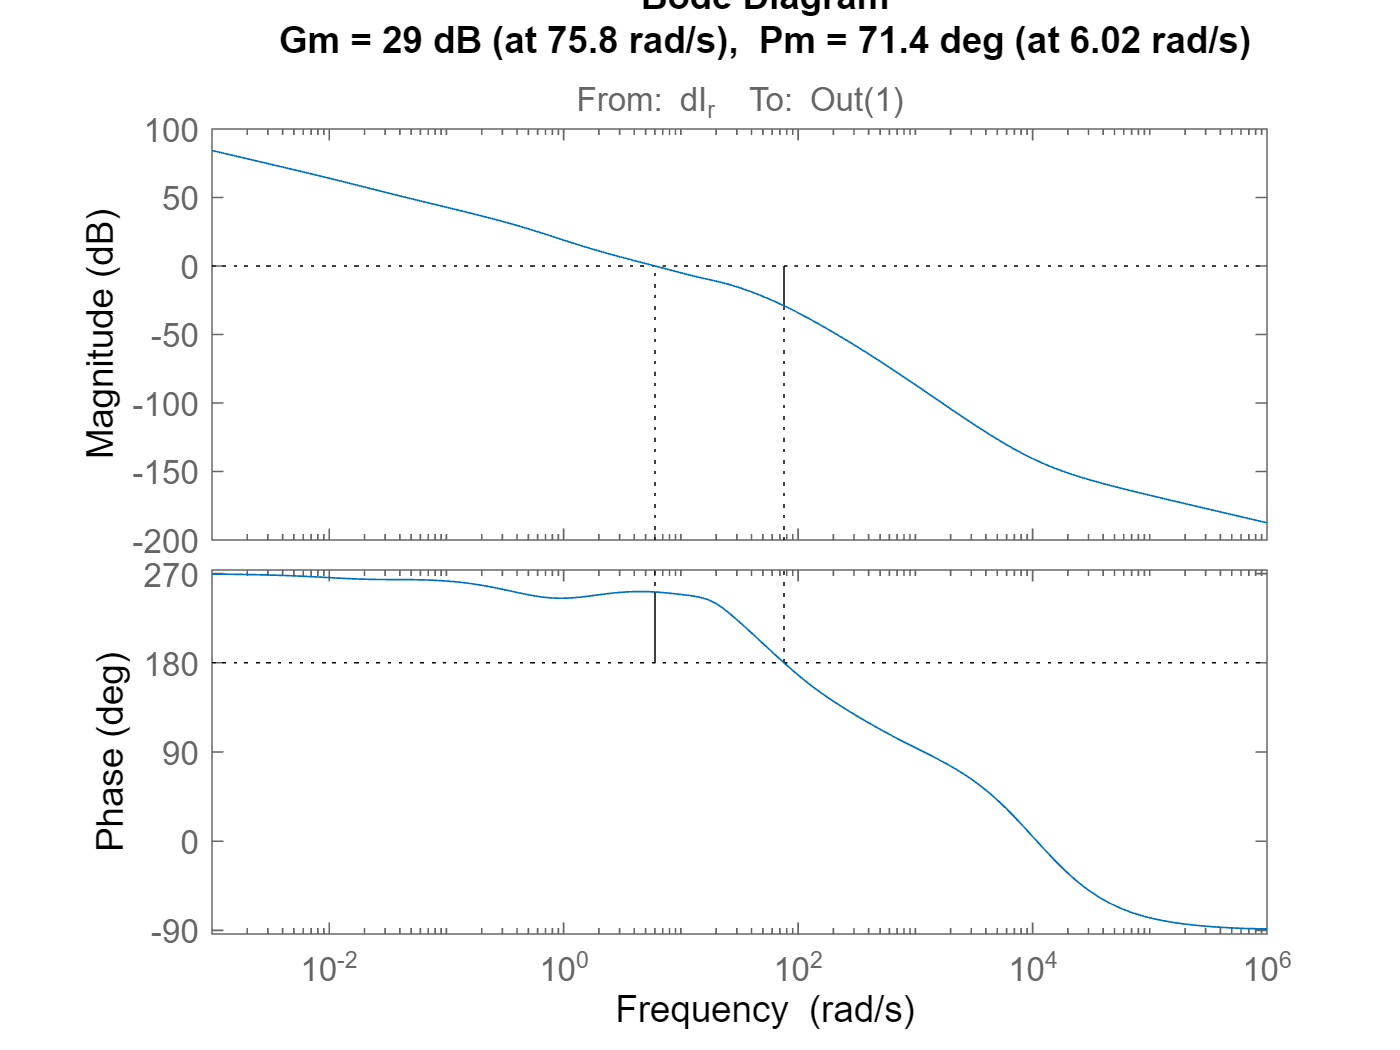

s = tf('s');
R_contr = 0.8*(1+10/s);

margin(R_contr*R_olsys)

Let's try it

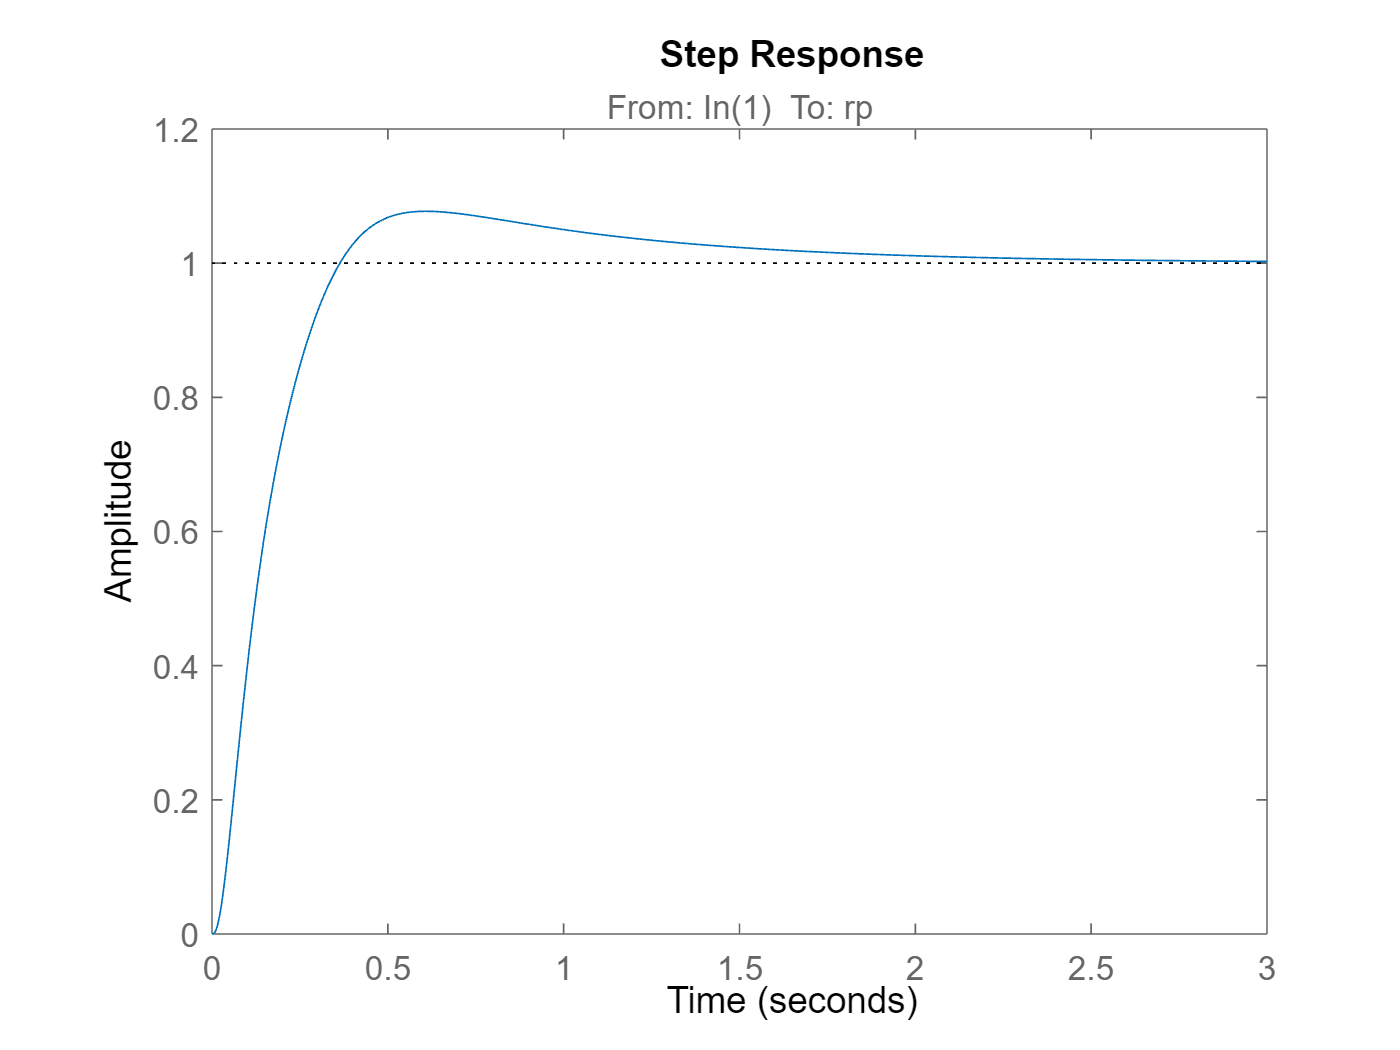

R_clsys = feedback(R_olsys*R_contr,1);
step(R_clsys)

How does this same controller behave on the $z_p$ channel? Let's see if we are lucky

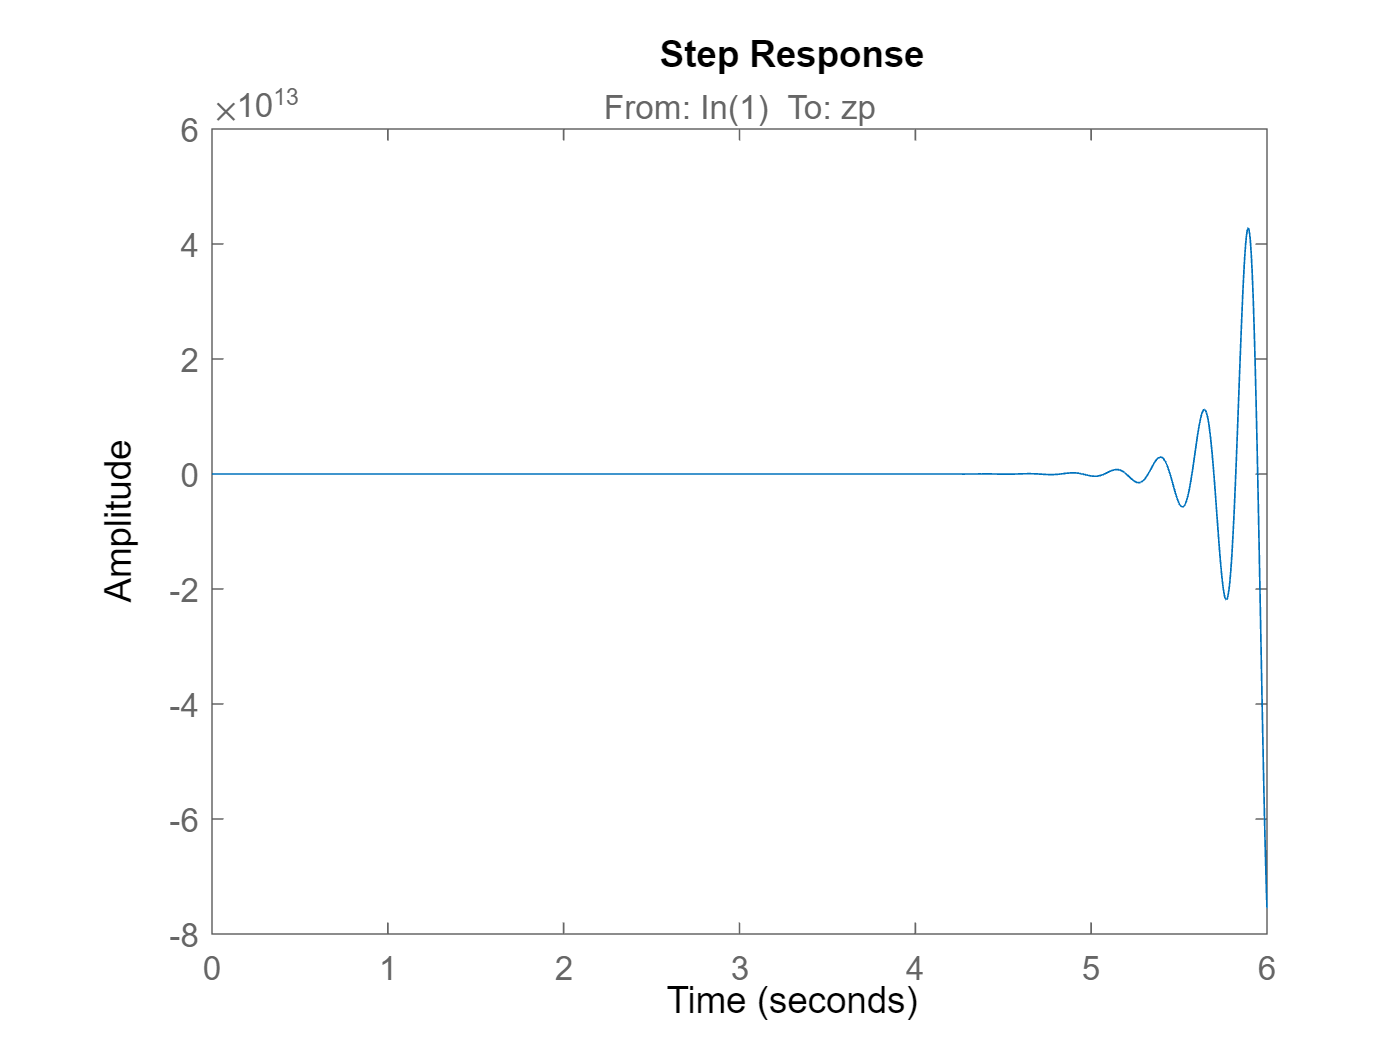

Z_olsys = RZ_decoupled_sys(2,2);
Z_contr = R_contr;

Z_clsys = feedback(Z_olsys*Z_contr,1);
step(Z_clsys)

:( 

Let's start again

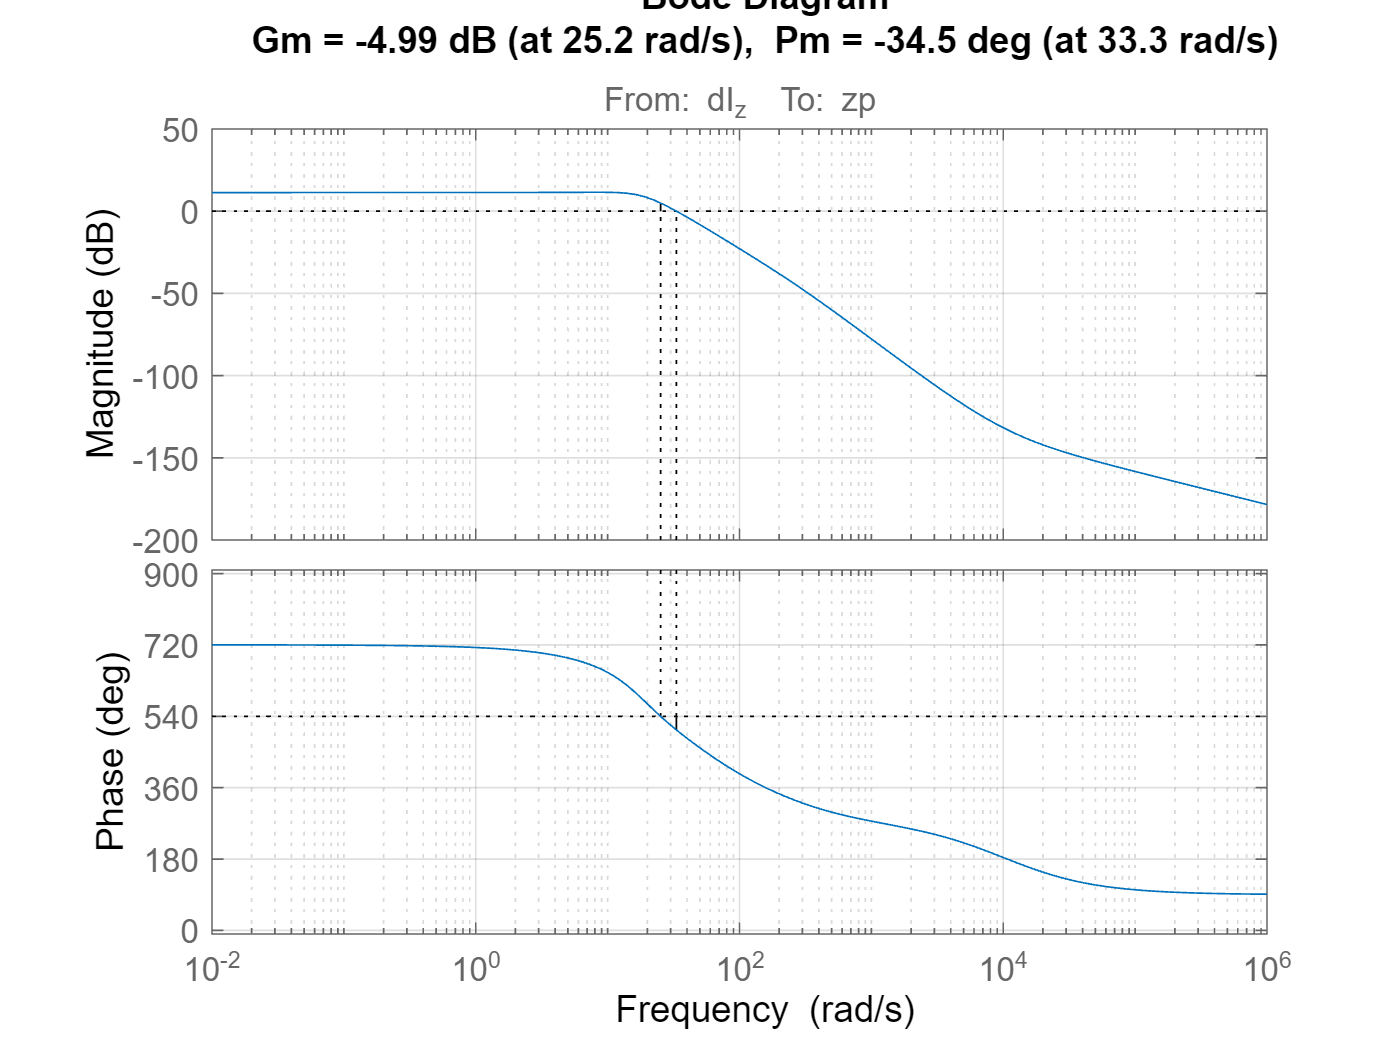

margin(Z_olsys), grid on

Terrible! We definitely need to increase the phase margin. If we look at our PI, we have:


$$PI(s) = K_I \frac{1+sT_I}{s}$$


To increase our phase margin, we may place our zero somewhere between 5 and 10 rad/s, so $T_I = 0.1 \div 0.2$

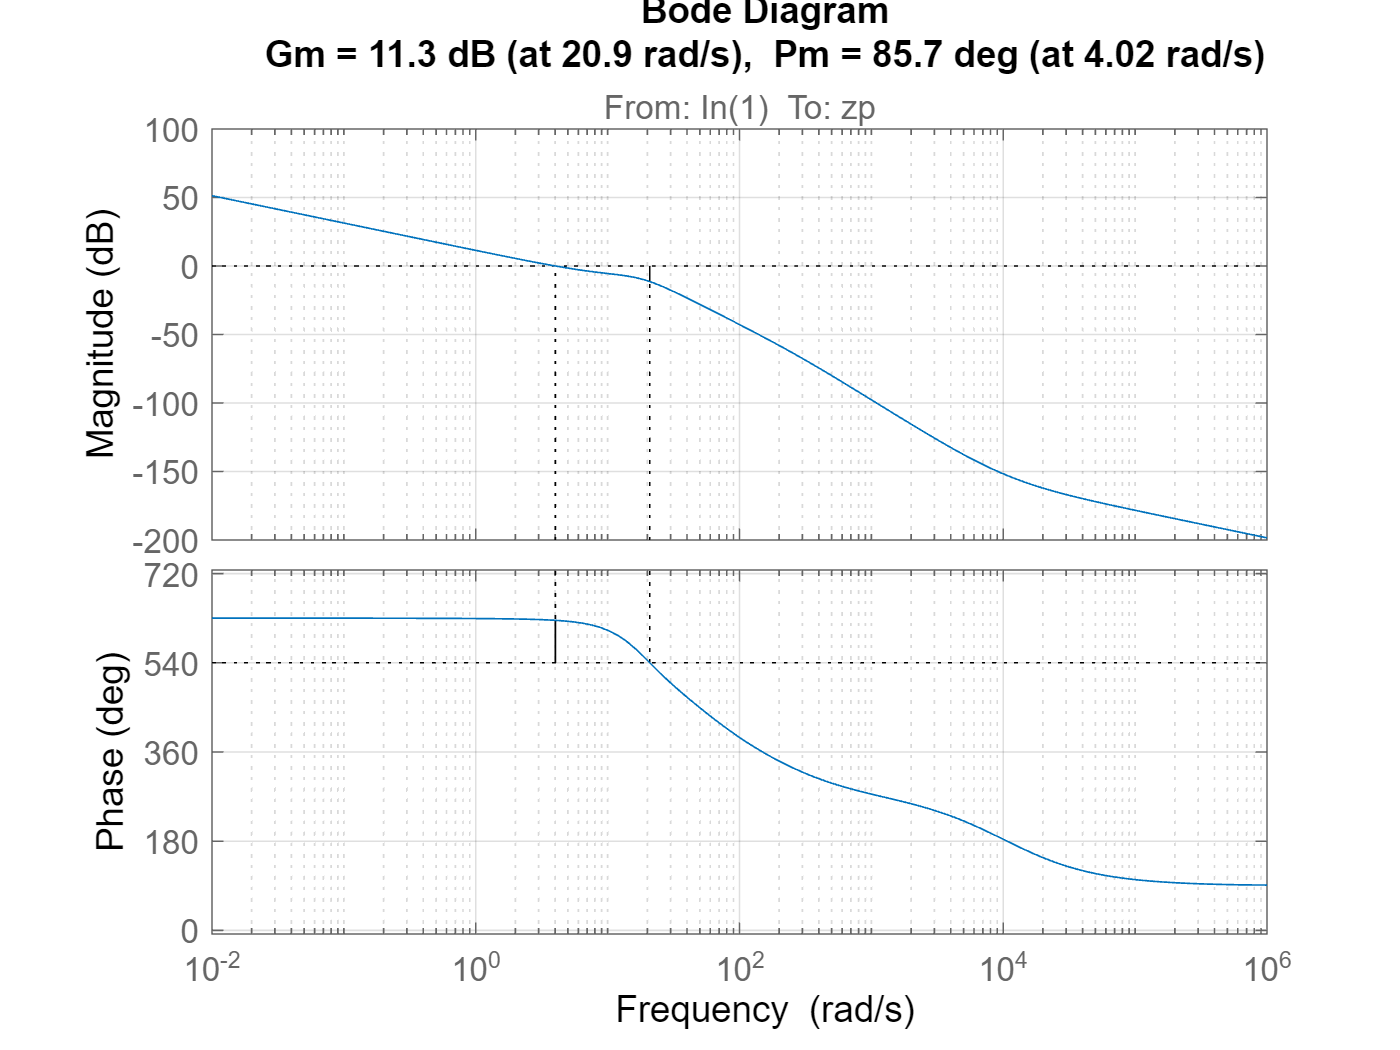

Z_contr = (1+0.1*s)/s;
margin(Z_olsys*Z_contr), grid on

Not too bad. We can increase the bandwith a little

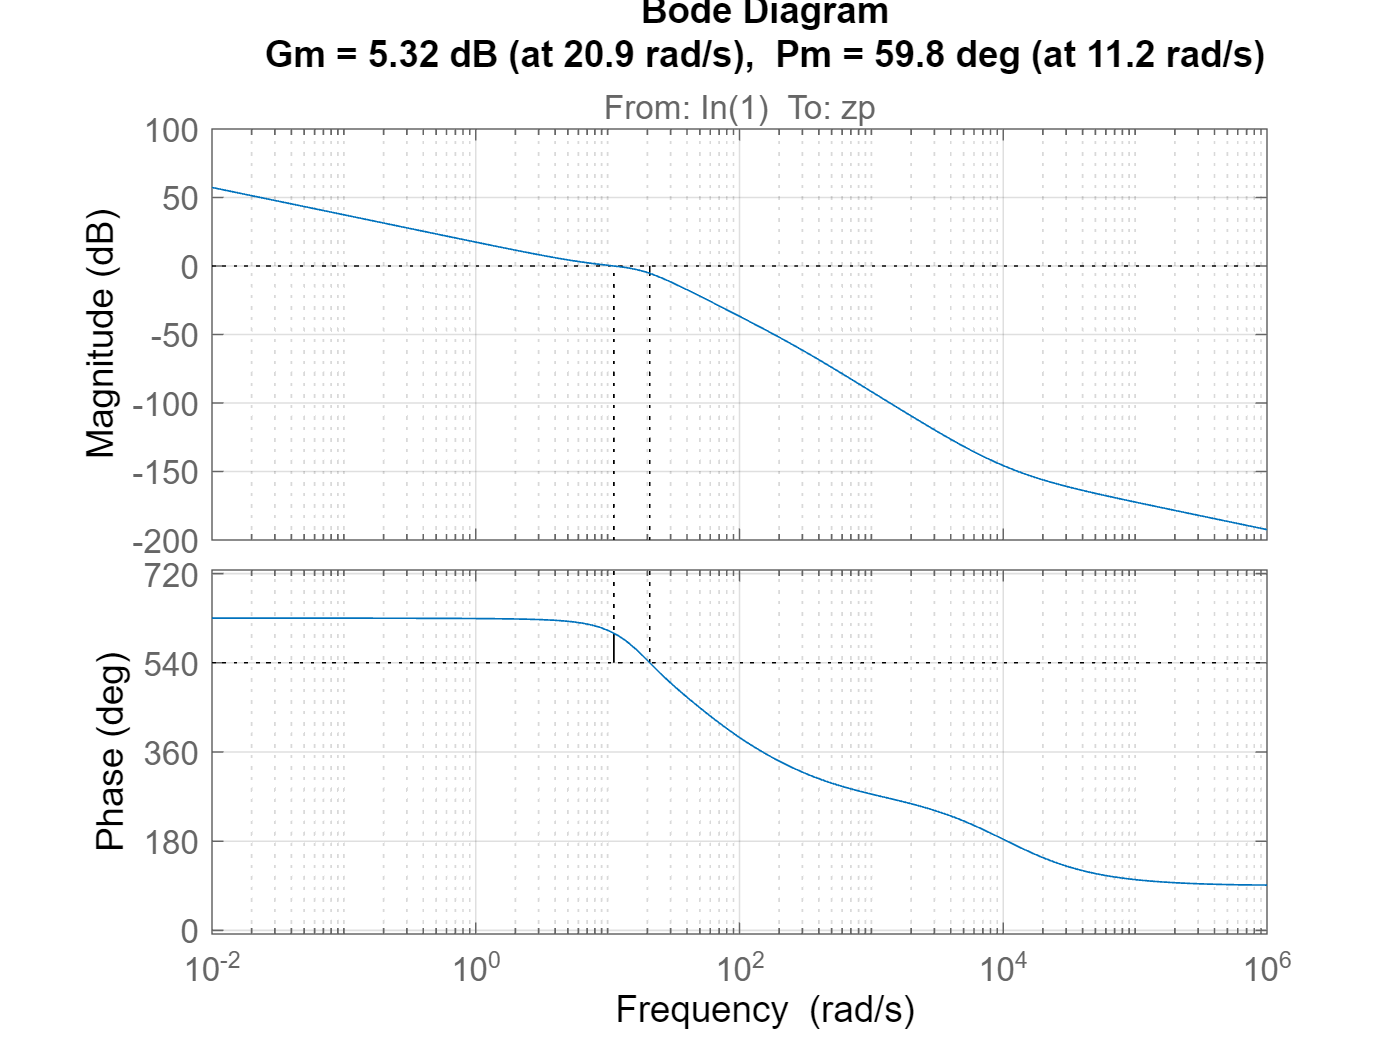

Z_contr = Z_contr * 2;
margin(Z_olsys*Z_contr), grid on

Reasonable, similar phase margin as before and even a larger bandwidth. Let's try it

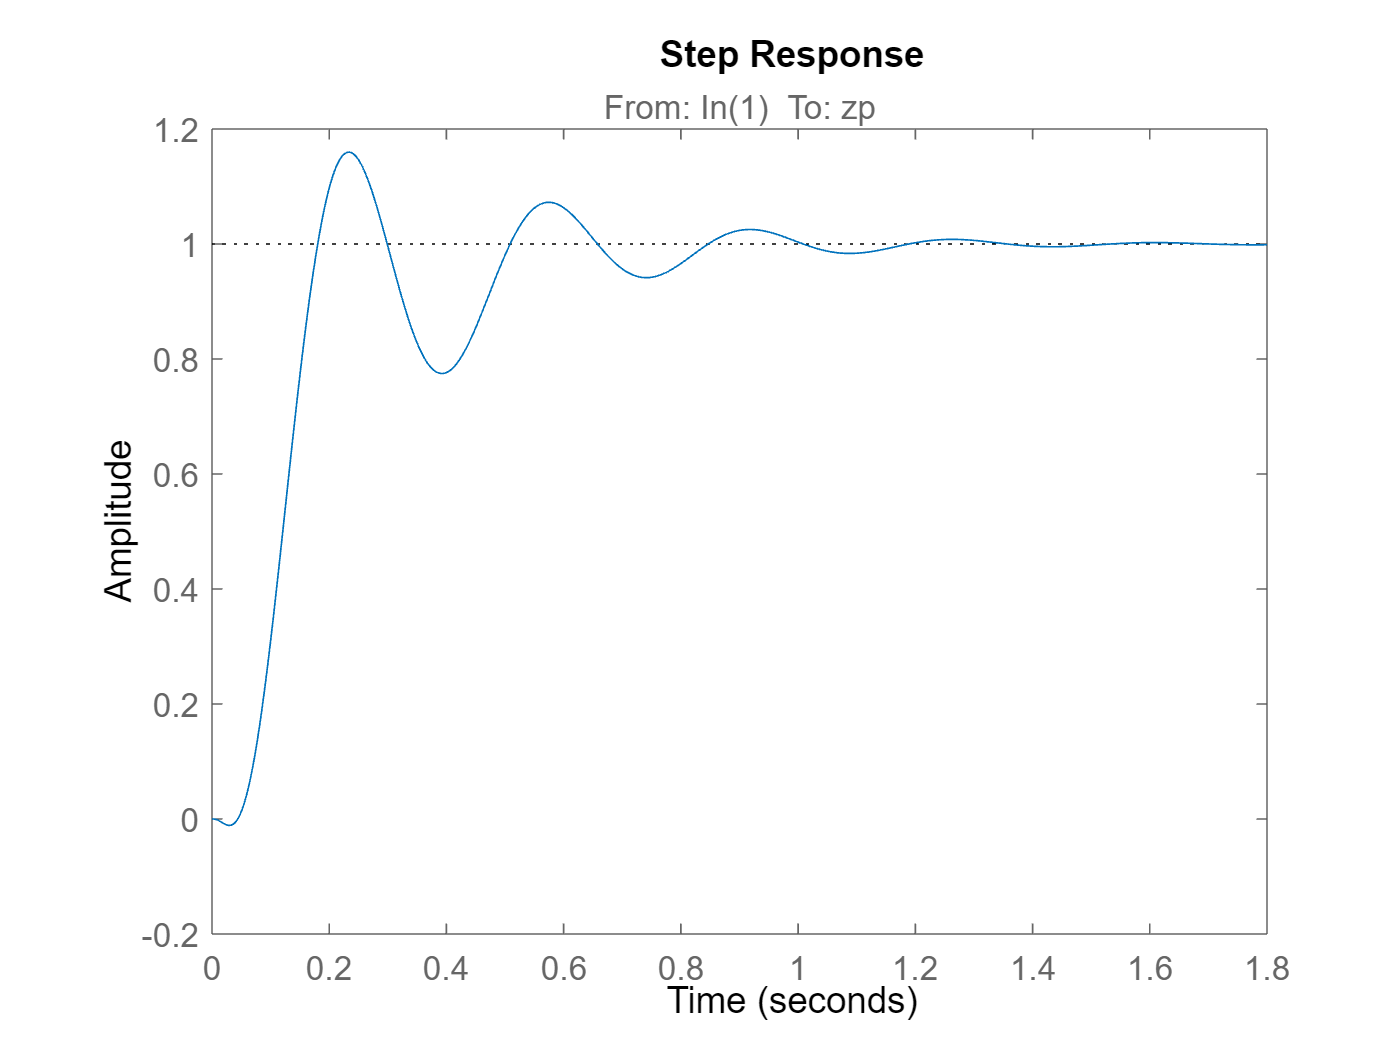

Z_clsys = feedback(Z_olsys*Z_contr,1);
step(Z_clsys)

Acceptable. Finally, let's see what happens when we put it all together

RZ_contr = [R_contr 0; 0 Z_contr];
RZ_contr.inputname = {'rp','zp'};
RZ_contr.outputname = {'dI_r','dI_z'};
RZ_olsys = series(RZ_contr,RZ_decoupled_sys,'name');
RZ_clsys = feedback(RZ_olsys,eye(2));

We now test our controller on a centroid position variation. Assume we want to move the plasma 2cm outwards and 1.5cm upwards, with a ramp of 4 s:

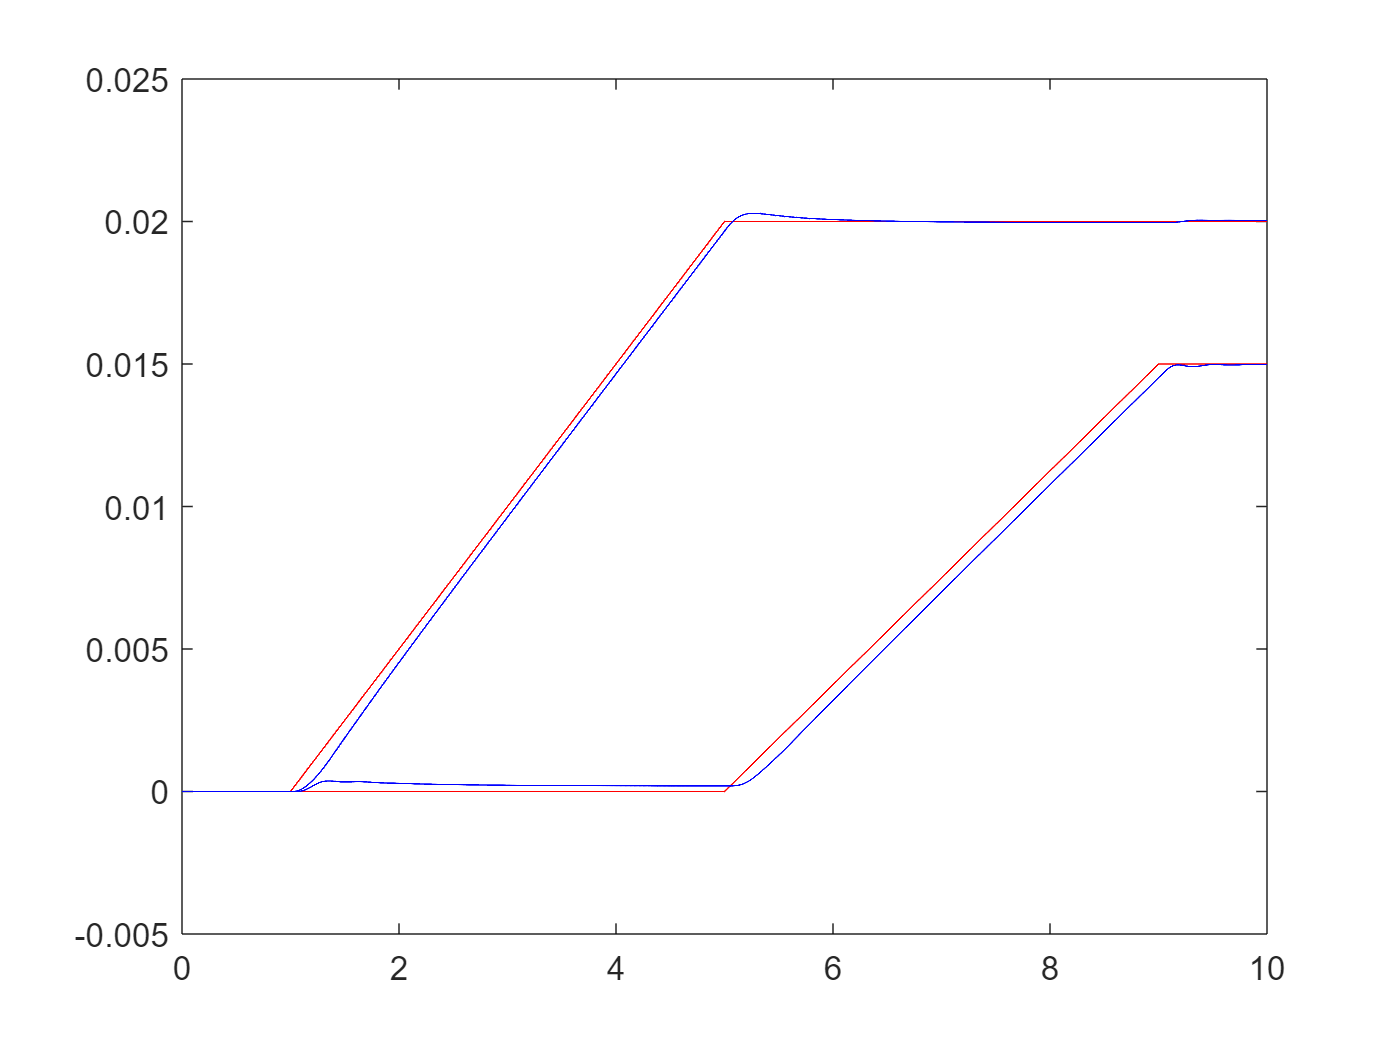

% Build reference
t = [0 1 5 9 10]';
dr = [0 0 2e-2 2e-2     2e-2;
      0 0 0    1.5e-2 1.5e-2]';

Tspan = (t(1):1e-3:t(end))';
dr = interp1(t,dr,Tspan);

% Simulate plant
[y,t] = lsim(RZ_clsys,dr,Tspan,'zoh');

% Plot results
figure
plot(Tspan,dr,'r',t,y,'b')

The decoupling works pretty well!

Finally, let's save everything for later use

save ./data/RZ_contr RZ_contr dI_r dI_z RZ_clsys